## Robust and Nonlinear Control, EEN050. 

### Assignment 2 on robust controller design.

%clear vars
%close all
%clc

1st order TF: $k\frac{s + z}{s + p}$

DC gain: $s = 0$.

Low freq. gain: $s \rightarrow 0$

High freq. gain: $s \rightarrow \infty$

Crossover freq.: $|L(j\omega_c)| = 1$

Magnitude: 

Or just use *makeweight()*...

### Wr

A second order dampened system is given by: $s^2 + 2\zeta\omega_ns + \omega_n^2$. The system is critically dampened if $\zeta = 1$.

Reference value $r$ is scalar, 1x1. Meassured output $y$ is 3x1, with $y_1 = \alpha$. $\Rightarrow W_r$ is 3x1

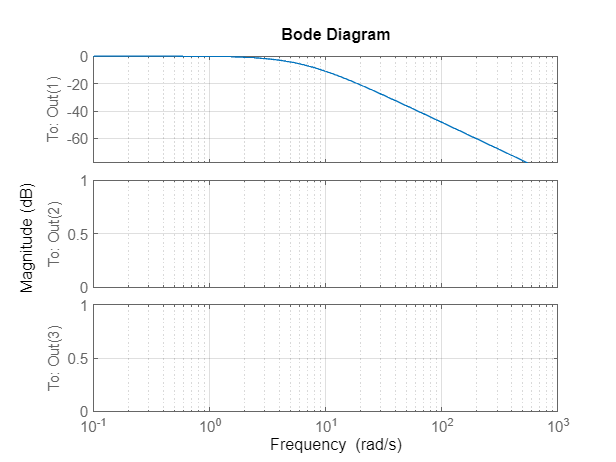

omega_wr = 6.25;
wr1 = tf([omega_wr^2],[1, 2*omega_wr, omega_wr^2]);
Wr = [wr1; 0; 0];
bodemag(Wr), grid on

### We

Let $z_e$ be 1x1 for now $\Rightarrow$$W_e$ is 1x3. This way we only look at angle of attack error

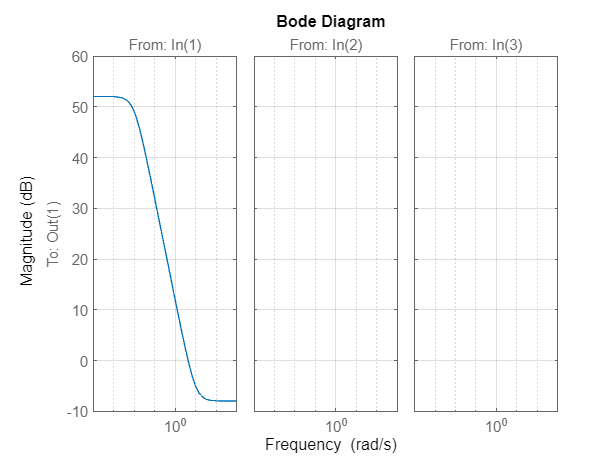

DC_we = 400; % amplitude
omega_we_c = 4.3; % rad
HF_we = 0.4; % amplitude
we1 = makeweight(DC_we, omega_we_c, HF_we);
We = [we1, 0, 0];
bodemag(We), grid on

### Wp

Let $z_p$ be 2x1 $\Rightarrow W_p$ is 2x3. We only look at angle of attack and normal acceleration of CoG.

wp1_w = makeweight(2.5, 0.45, 0.015); % weight on alpha, for synthesis and robustness analysis
wp1_nw = 1;                           % no weight on alpha for LQI comparisson
wp2 = makeweight(2.5, 0.7, 0.0063); % alpha_n
Wp_w = [wp1_w, 0, 0; 0, 0, wp2]; % 2x3
Wp_nw = [wp1_nw, 0, 0; 0, 0, wp2]; % 2x3

### Wu

Control input vector $u$ is 2x1 and $z_u$ is scalar $\Rightarrow W_u$ is 1x2.

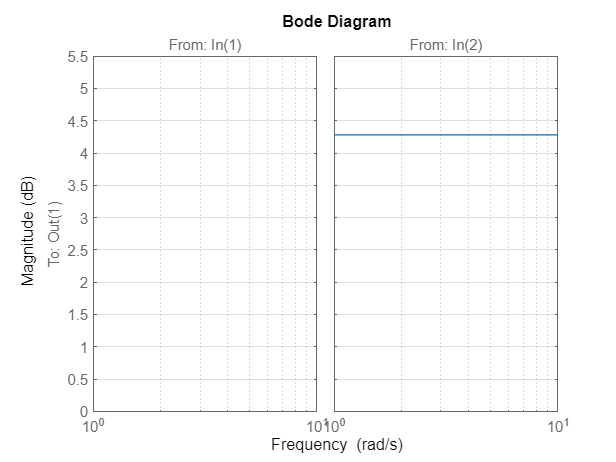

wu11 = 0;
wu21 = tf(1/deg2rad(35),1);
Wu = [wu11, wu21]; % 1x2
bodemag(Wu), grid on

### Wn

Size only depends on $v_{\tilde{y}} = W_n \cdot n$, with $v_{\tilde{y}}$ is 3x1 and $n$ is 3x1. That makes $W_n$ 3x3.

Additive noise on measured outputs: [ $\alpha$ (deg); $q$ (rad/s) (pitch rate); $\alpha_n$ (ft/s^2)  (normal acceleration of CoG)]

noise_a = rad2deg(0.001); % convert to deg
noise_q = 0.001;
noise_an = 0.001*3.28084; % convert to ft/s2
Wn = diag([noise_a, noise_q, noise_an])

Wn =     0.0573         0         0
         0    0.0010         0
         0         0    0.0033


### Wd

Disturbance only acts on deflection, which is the 2nd input. $W_d$ is 2x2.

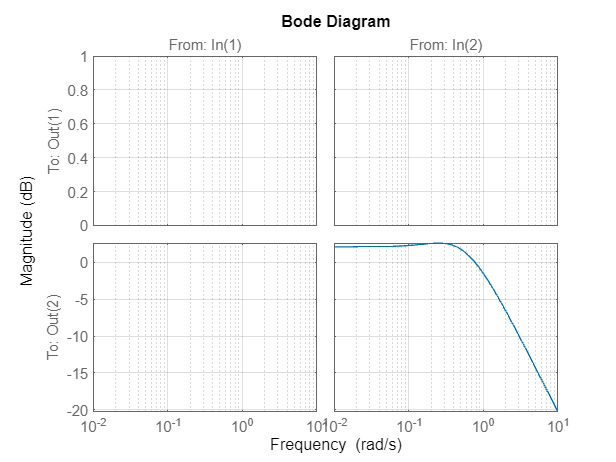

wd11 = 0;
wd22 = tf([0.9751, 0.2491], [1, 0.885, 0.1958]);
Wd = [wd11, 0; 0, wd22];
bodemag(Wd), grid on

### Wm

Should be 2x2 for dimensions to match: $z_u = W_uW_mu_{\Delta}$.

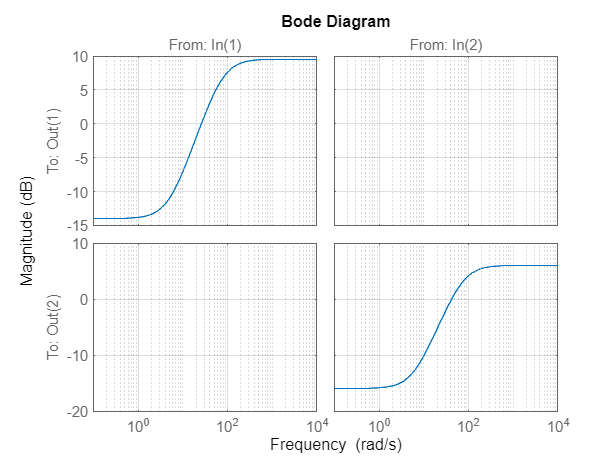

wm11 = makeweight(0.2, 26, 3);
wm22 = makeweight(0.16, 42, 2);
Wm = [wm11, 0; 0, wm22];
bodemag(Wm), grid on

Ga_ss = Ga;
Ga = tf(Ga);
Gn_ss = Gn;
Gn = tf(Gn);

% real P model (weight on zp_alpha)
P12 = [Ga;-We*Gn*Ga;Wp_w*Gn*Ga;Wu*Ga];
P21 = [zeros(1,2), zeros(1,2),eye(1),zeros(1,3);
    Gn*Wm, Gn*Wd, zeros(3,1), Wn];
P22 = [zeros(1,2); Gn*Ga];
P11_left = [-We*Gn*Wm, -We*Gn*Wd, We*Wr;
    Wp_w*Gn*Wm, Wp_w*Gn*Wd, zeros(2,1);
    Wu*Wm, Wu*Wd, zeros(1,1)];
P11_right = zeros(4,3);
P11_temp = [P11_left, P11_right];
P11 = [zeros(2,8);P11_temp];

P_w = [P11, P12; P21, P22];

% simplified P used for comparisson later (no weight on zp_alpha)
P12 = [Ga;-We*Gn*Ga;Wp_nw*Gn*Ga;Wu*Ga];
P21 = [zeros(1,2), zeros(1,2),eye(1),zeros(1,3);
    Gn*Wm, Gn*Wd, zeros(3,1), Wn];
P22 = [zeros(1,2); Gn*Ga];
P11_left = [-We*Gn*Wm, -We*Gn*Wd, We*Wr;
    Wp_nw*Gn*Wm, Wp_nw*Gn*Wd, zeros(2,1);
    Wu*Wm, Wu*Wd, zeros(1,1)];
P11_right = zeros(4,3);
P11_temp = [P11_left, P11_right];
P11 = [zeros(2,8);P11_temp];

P_nw = [P11, P12; P21, P22];

[K_h2, N_h2_w, gamma_h2] = h2syn(minreal(P_w), 4, 2);

100 states removed.


[K_hinf, N_hinf_w, gamma_hinf] = hinfsyn(minreal(P_w), 4, 2);

100 states removed.


gamma_h2

gamma_h2 = Inf

gamma_hinf

gamma_hinf = 22.6428

size(K_h2)

State-space model with 2 outputs, 4 inputs, and 17 states.


size(K_hinf)

State-space model with 2 outputs, 4 inputs, and 17 states.


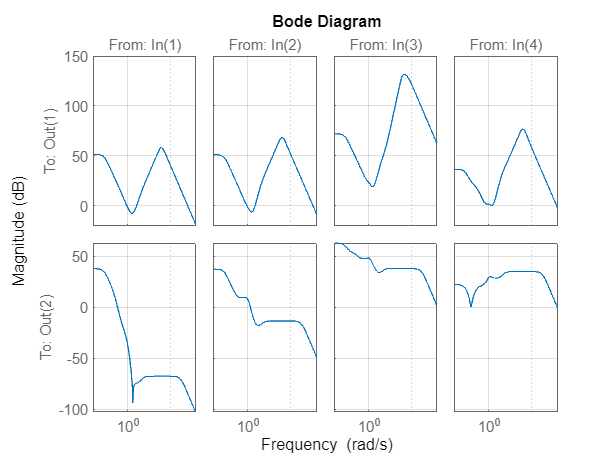

bodemag(K_h2), grid on

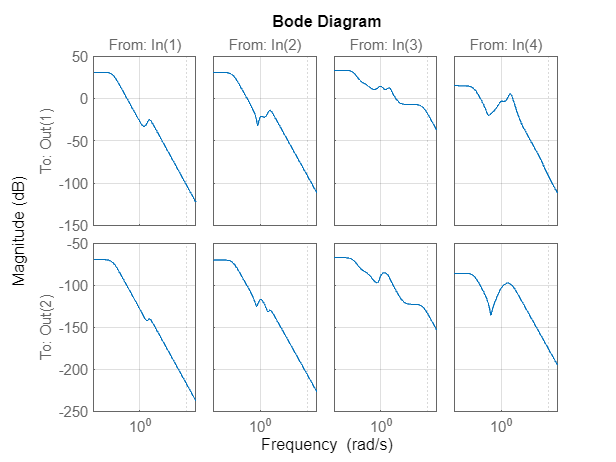

bodemag(K_hinf), grid on